# LC Optimization

## Constants

C_Dee = 78*10^-12; % in Farads -- maybe want to remeasure
min_freq = 6*10^6; max_freq = 16*10^6; % in Hz

## Variables

L = [1.1:0.1:10]*10^-6; % choose discrete values for L, in H
RAc = [50]*10^-3; % in Ohm -- somehow this relates to L
C = (0:150)*10^-12; % in F -- actually (mostly) continuous for vacuum C
P = [100:100:1500]; % in W -- can probably tune with hardware

## Calculations

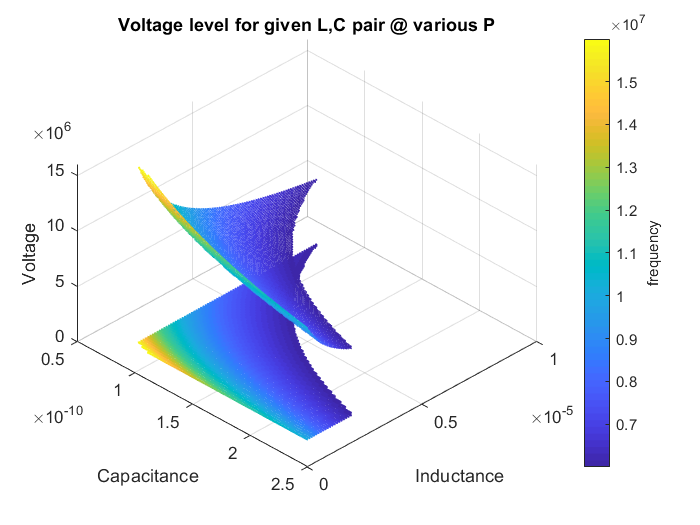

C_eq = C+C_Dee; % calculate parallel capacitance
[Cg, Lg] = meshgrid(C_eq, L); % define meshgrid to compute something as a function of (L,C) ordered pair

freq = 1./(2*pi*sqrt(Lg.*Cg)); % define freq array as freq(L,C) for each (L,C) pair
ind = (freq >= min_freq) & (freq <= max_freq); % create logical array to see which indices (l,c) puts us within our range

figure(100), scatter3(Cg(ind==1),Lg(ind==1),freq(ind==1),1,freq(ind==1));
title('Frequency for given L,C pair');
xlabel('Capactance'),ylabel('Inductance'),zlabel('Frequency');
view(135,45);

% -------- Some notes:
% RAc should change for each L - how to figure this out?
% we assumed P was set at 1500 - 
% maybe better to plot P as one of the X-Y axes and generate level surfaces
% for each discrete L value.
% need to verify the indices where freq in proper range

for n = 1:length(P)
    Vpp = 2*sqrt(2*P(n)*Lg./(RAc*Cg)).*ind; % compute Vpp for given power, at each (L,C)
        % multiply by our logical array s.t. V(L,C) for (L,C) pair out of
        % freq. range returns 0, and keeps original value o.w.
    
    figure(1), hold on, scatter3(Cg(Vpp>0),Lg(Vpp>0),Vpp(Vpp>0),1,freq(Vpp>0)); % use scatter plot to show data
        % uses conditionals to plot only the data within our freq. range
        % parameter 4 specifies point size
        % parameter 5 specifies color map (change color for different Vpp
        % values).
    title('Voltage level for given L,C pair @ various P')
    xlabel('Capacitance'), ylabel('Inductance'),zlabel('Voltage');
    view(45,45);
    
    % -- just for scatter3 vs surface comparison
    %{
    if n==1
    figure(n+100), surfc(Cg,Lg,Vpp)
    title('Voltage level for given L,C pair')
    xlabel('Capacitance'), ylabel('Inductance'),zlabel('Voltage');
    view(45,45);
    end
    %}
    
end
figure(1), c=colorbar; ylabel(c,'frequency');